fnorm_with%['C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']



batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

%batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]
%batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]
% src = trainData(1); % src has invaild item on index 1
% dest = trainData2(8); % dest has vaild item on index 1
% merge = merge_struct(trainData(1),trainData2(8));

src = trainData(2); % src has invaild item on index 1
dest = trainData2(9); % dest has vaild item on index 1
merge = merge_struct(trainData(2),trainData2(9));

% verify
src.cycle_life

ans = 1179

dest.cycle_life

ans = 982

src.cycle_life + dest.cycle_life - 1

ans = 2160

merge.cycle_life

ans = 2160

length(src.summary.QDischarge)

ans = 1178

length(dest.summary.QDischarge)

ans = 981

length(merge.summary.QDischarge)

ans = 2159

%%%%%%%%%%%
src.summary.QDischarge(1)

ans = 0

src.summary.QDischarge(2)

ans = 1.0753

src.summary.QDischarge(end-1)

ans = 1.0386

src.summary.QDischarge(end)

ans = 1.0382

%%%%
dest.summary.QDischarge(1)

ans = 1.0245

dest.summary.QDischarge(2)

ans = 1.0265

dest.summary.QDischarge(end-1)

ans = 0.8802

dest.summary.QDischarge(end)

ans = 0.8800

%%%%
merge.summary.QDischarge(1)

ans = 0

merge.summary.QDischarge(2)

ans = 1.0753

merge.summary.QDischarge(length(src.summary.QDischarge)-1)

ans = 1.0386

merge.summary.QDischarge(length(src.summary.QDischarge))

ans = 1.0382

merge.summary.QDischarge(length(src.summary.QDischarge)+1)

ans = 1.0245

merge.summary.QDischarge(length(src.summary.QDischarge)+2)

ans = 1.0265

merge.summary.QDischarge(end-1)

ans = 0.8802

merge.summary.QDischarge(end)

ans = 0.8800

new_index = 1;
BAT = zeros();
BAT = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));

% batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))
% #remove batteries that do not reach 80% capacity
% del batch1['b1c8']
% del batch1['b1c10']
% del batch1['b1c12']
% del batch1['b1c13']
% del batch1['b1c22']

skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        else
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batNum;
    end
end


batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]

batch1_keys = 1×5 string array
    "b1c1"    "b1c2"    "b1c3"    "b1c4"    "b1c5"


batch1_fix = [1 2 3 4 5];

batchNum = 2;
for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if find(ismember(batNum,batch2_fix)) 
            idx = find(ismember(batNum,batch2_fix)) ;
            temp = trainData(batch1_fix(idx));
            src = temp;
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            BAT(batch1_fix(idx)) = struct();
            BAT(batch1_fix(idx)) = merge;
%             for idx_new=1:length(BAT)
%                 if find(ismember(batch1_keys(idx),BAT(idx_new).key))  
%                     BAT(idx_new)= extract_feature_all_new_bat_soc_v3(1,batch1_fix(idx),merge);
%                 end     
%             end
            
        else
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batNum;
    end
end

Subscripted assignment between dissimilar structures.



batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batNum;
    end
end

idx = 1
for idx_new=1:length(BAT)
        if find(ismember(batch1_keys(idx),BAT(idx_new).key))  
            BAT(idx_new)= extract_feature_all_new_bat_soc_v3(1,batch1_fix(idx),merge);
        end     
end

%{
% merge 

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

continue_batch2 = [7 8 9 15 16 ];
continue_batch2 = continue_batch2 +1;
from_batch1 = [0 1 2 3 4];
from_batch1 = from_batch1 + 1;

% select = BAT([BAT.key == "b2c8")
%idx = find(strcmp({BAT.key},"b3c46",'IgnoreCase',true))
idx1 = find(strcmp({BAT.key},"b1c1"))


idx1 =

     []



idx = find(contains(BAT.key,'b1c1','IgnoreCase',true))


idx =

     []



%}

key = 'b3c46'

key = 'b3c46'

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]

batch2_keys = 1×5 string array
    "b2c8"    "b2c9"    "b2c10"    "b2c16"    "b2c17"


batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]

batch1_keys = 1×5 string array
    "b1c1"    "b1c2"    "b1c3"    "b1c4"    "b1c5"


batch1_keys1 = {'b1c1','b1c2','b1c3','b1c4','b1c5'}

batch1_keys1 = 1×5 cell array
    {'b1c1'}    {'b1c2'}    {'b1c3'}    {'b1c4'}    {'b1c5'}



bat2_num = zeros();
i=1;
for idx=1:length(BAT)
%     if contains(BAT(idx).key,batch2_keys)
%         bat2_num(i)= idx;
%         i = i+1;
%     end

    if find(ismember(batch2_keys,BAT(idx).key))  
        bat2_num(i)= idx;
        i = i+1;
    end
    
end
bat2_num

bat2_num =     49    50    51    57    58


bat1_num = zeros();
i=1;
for idx=1:length(BAT)
    %if strcmp(BAT(idx).key,batch1_keys)
    if find(ismember(batch1_keys,BAT(idx).key))  
        bat1_num(i)= idx;
        i = i+1;
    end
end
bat1_num

bat1_num =      1     2     3     4     5


newBat = struct();
for i=1:length(bat1_num)
    newbat(i)=BAT(bat1_num(i));
end
newbat_org = newbat;

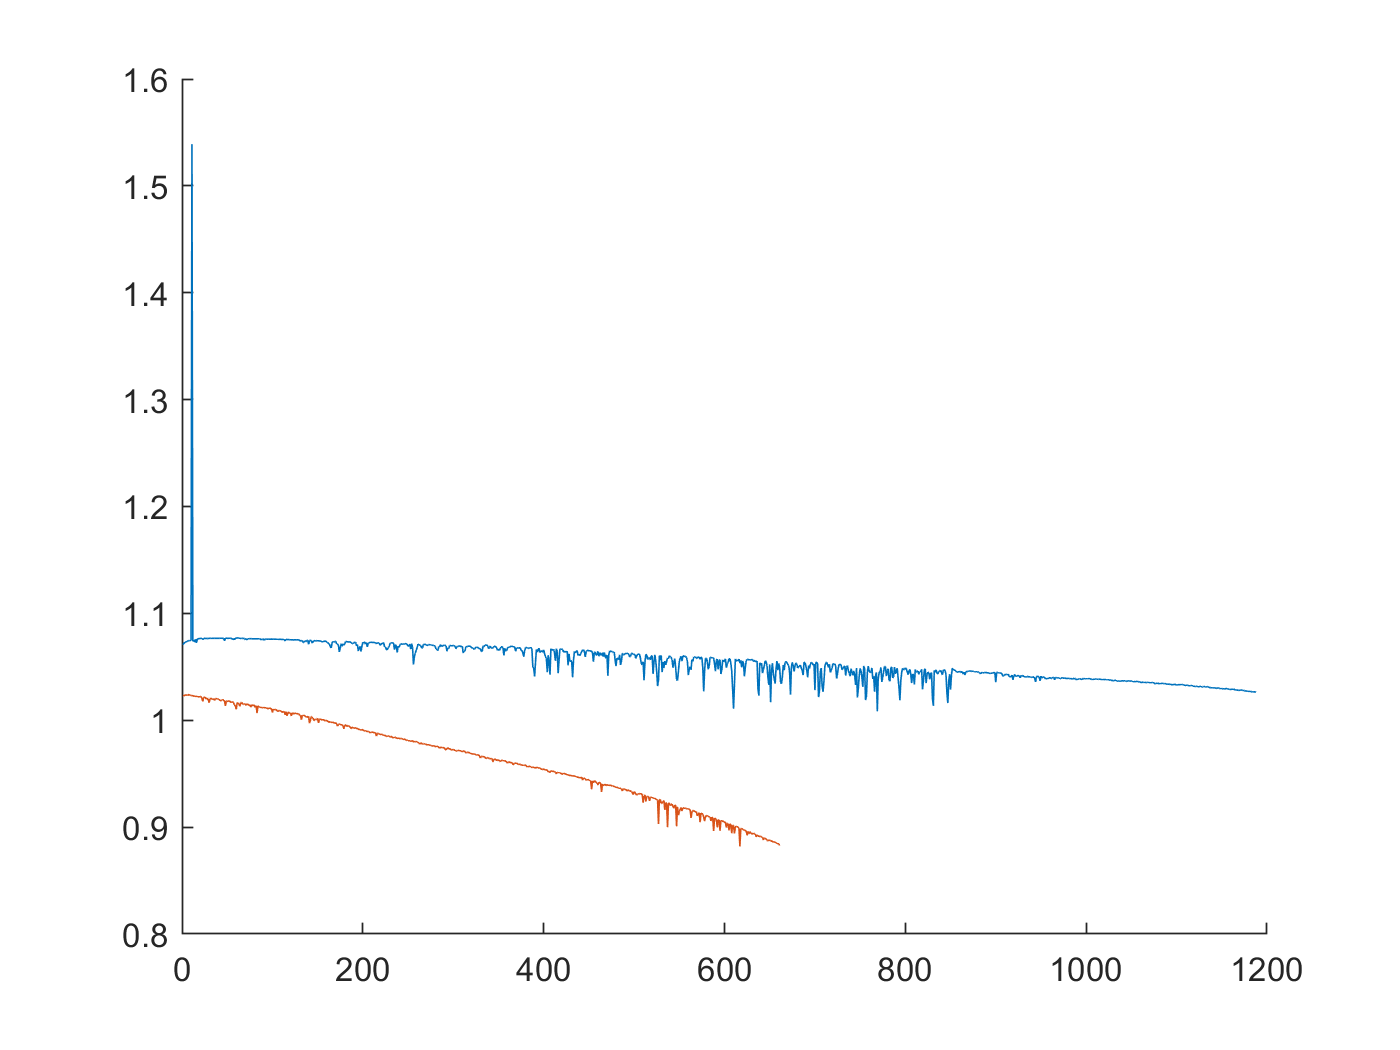


i =1;
figure
hold on
plot(newbat(i).cycle,newbat_org(1).QDischarge)
plot(BAT(bat2_num(i)).cycle,BAT(bat2_num(i)).QDischarge)

hold off

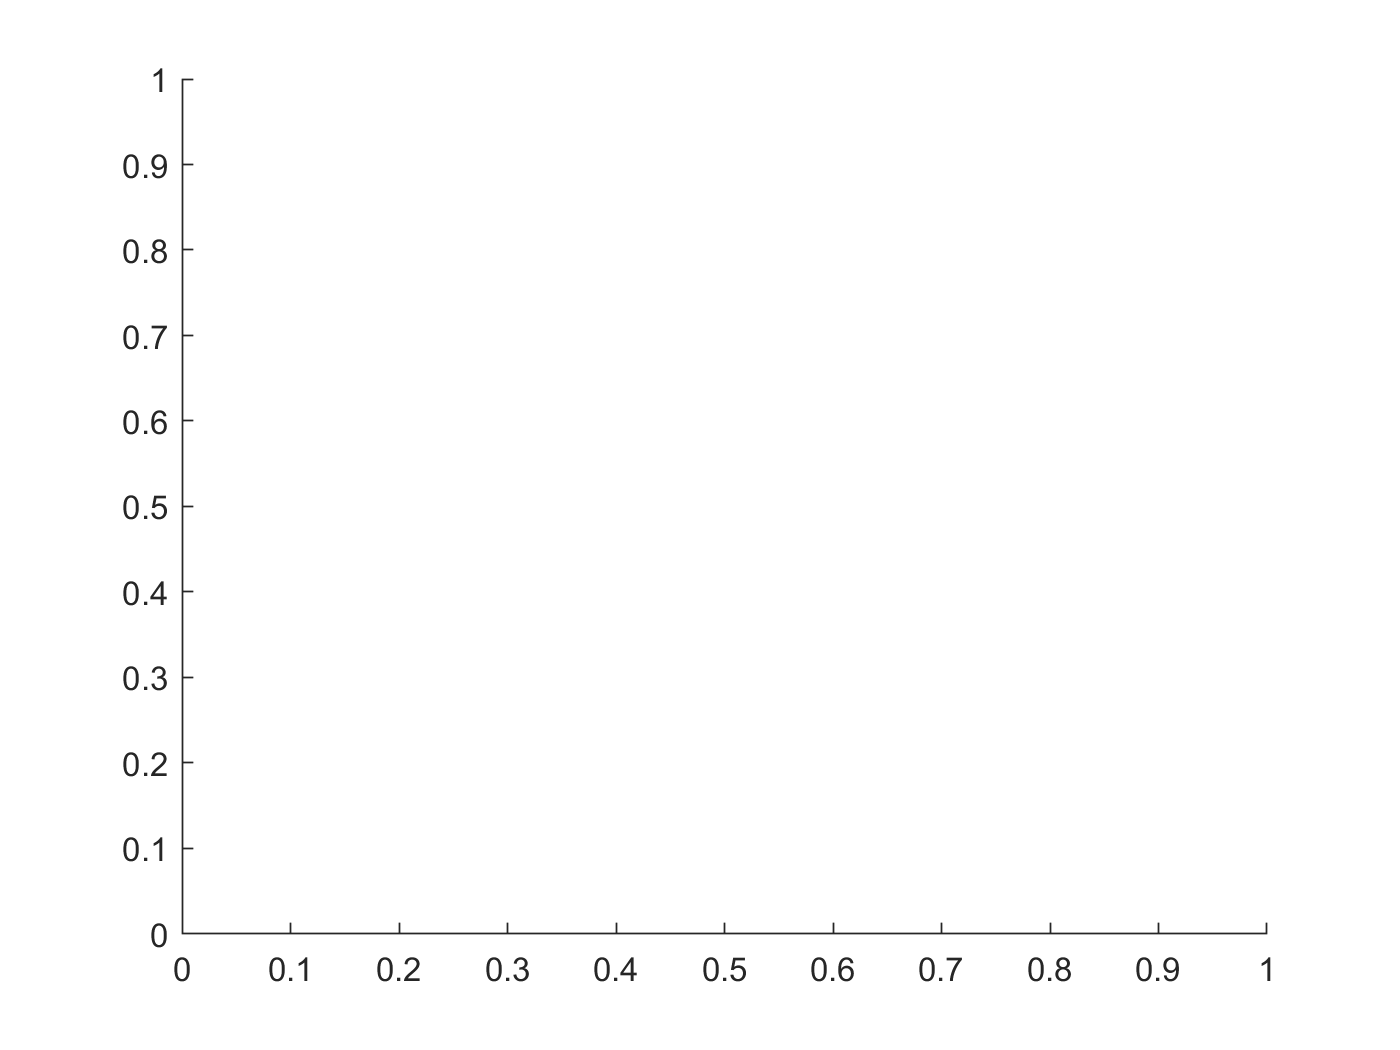

% Vd Qc
figure
hold on

plot(newbat_org(1).Qc)

Unrecognized field name "Qc".

plot(BAT(bat2_num(i)).Qc)
hold off



for i=1:length(bat2_num)
    %newbat(i).cycle_life = 
    newbat(i).cycle_life;
    BAT(bat2_num(i)).cycle_life;
    newbat(i).cycle_life = newbat(i).cycle_life + BAT(bat2_num(i)).cycle_life;
    newbat(i).cycle = linspace(1,newbat(i).cycle_life,newbat(i).cycle_life);
    newbat(i).chargetime = vertcat(newbat(i).chargetime,BAT(bat2_num(i)).chargetime);
    newbat(i).IR = vertcat(newbat(i).IR,BAT(bat2_num(i)).IR);
    newbat(i).QCharge = vertcat(newbat(i).QCharge,BAT(bat2_num(i)).QCharge);
    newbat(i).QDischarge = vertcat(newbat(i).QDischarge,BAT(bat2_num(i)).QDischarge);
    newbat(i).Tavg = vertcat(newbat(i).Tavg,BAT(bat2_num(i)).Tavg);
    newbat(i).Tmin = vertcat(newbat(i).Tmin,BAT(bat2_num(i)).Tmin);
    newbat(i).Tmax = vertcat(newbat(i).Tmax,BAT(bat2_num(i)).Tmax);
    newbat(i).Vdlin = vertcat(newbat(i).Vdlin,BAT(bat2_num(i)).Vdlin);
    newbat(i).Vc = horzcat(newbat(i).Vc,BAT(bat2_num(i)).Vc);
    newbat(i).Tc = horzcat(newbat(i).Tc,BAT(bat2_num(i)).Tc);
    newbat(i).Vd = horzcat(newbat(i).Vd,BAT(bat2_num(i)).Vd);
    newbat(i).Td = horzcat(newbat(i).Td,BAT(bat2_num(i)).Td);
    newbat(i).QDischargeSmooth = horzcat(newbat(i).QDischargeSmooth,BAT(bat2_num(i)).QDischargeSmooth);
    %newbat(i).QDischargePolyMdl = vertcat(newbat(i).QDischargePolyMdl,BAT(bat2_num(i)).QDischargePolyMdl);
    %newbat(i).QDischargePolyfit = vertcat(newbat(i).QDischargePolyfit,BAT(bat2_num(i)).QDischargePolyfit);
   
end

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

new_index = 1;
batchNum = 1;
clear batch1_info;
clear batch1_data;

max_cycle=1;
for batNum = 1:size(trainData,2);
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if trainData(batNum).cycle_life > max_cycle 
            max_cycle = trainData(batNum).cycle_life;
        end
    end
end
max_cycle = max_cycle-1;



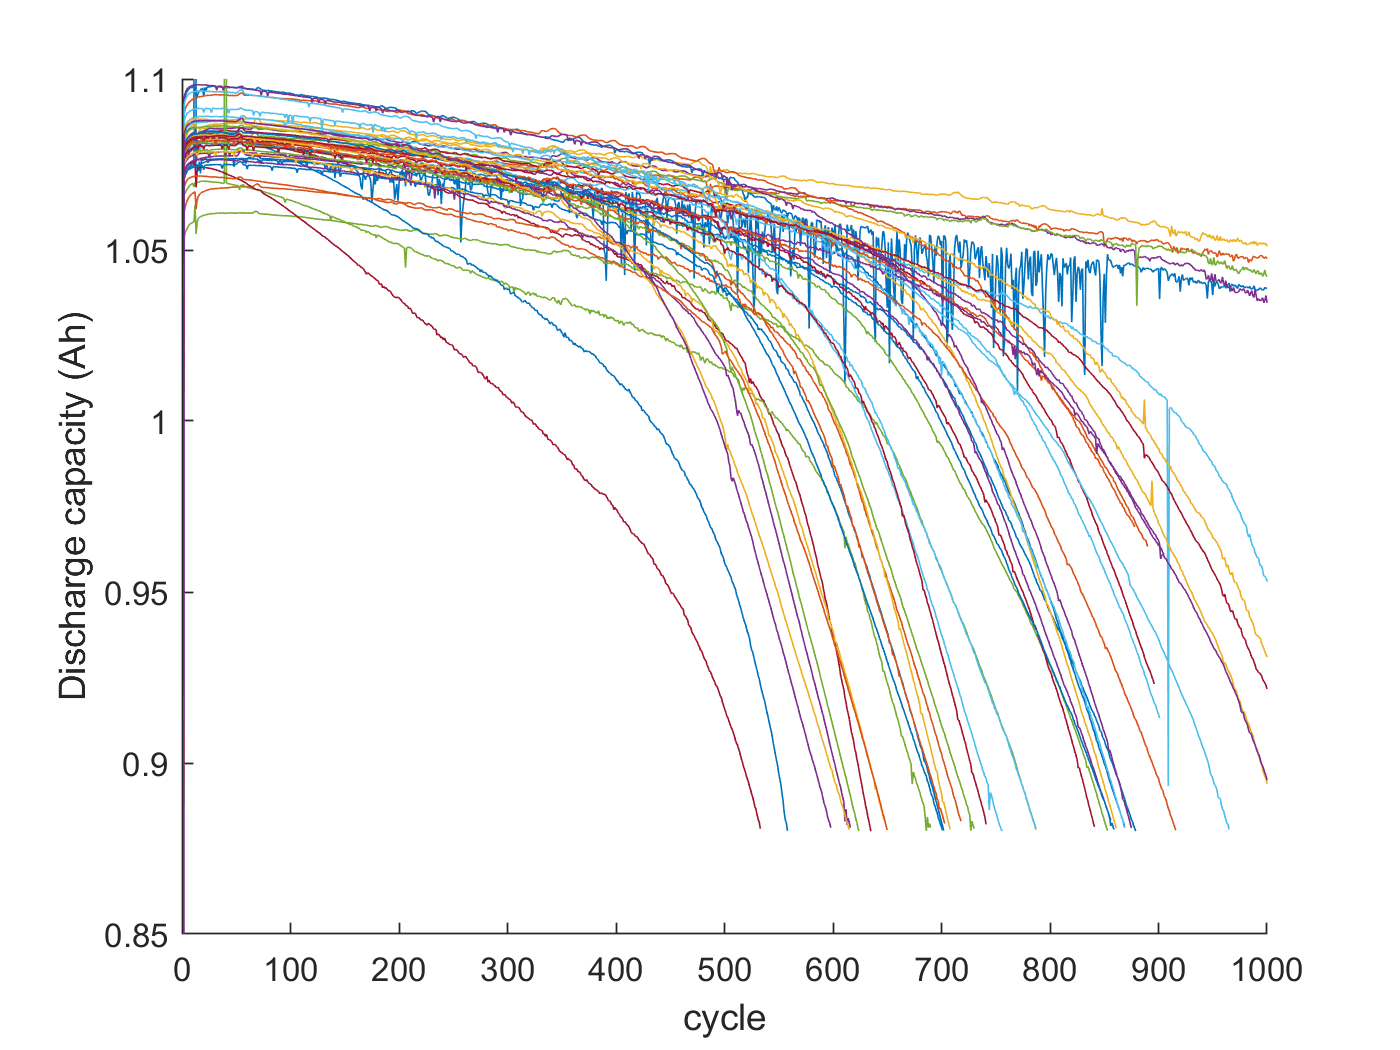

ignore = [];
ignore_index =1;
figure, hold on;
%trainData_cycle= zeros() %1,size(trainData,2));
%trainData_QDischarge= zeros(1,size(trainData,2));

new_index = 1;
for i = 1:size(trainData,2)
    if numel(trainData(i).summary.cycle) == numel(unique(trainData(i).summary.cycle))
      plot(trainData(i).summary.cycle, trainData(i).summary.QDischarge);     
      %trainData_cycle(new_index) = trainData(i).summary.cycle;
      %trainData_cycle = [ trainData_cycle' ; trainData(i).summary.cycle' ];
      %trainData_QDischarge(new_index) = trainData(i).summary.QDischarge;
      %new_index = new_index+1;
    else
      ignore(ignore_index) = i;
      ignore_index = ignore_index +1;
    end
end
ylim([0.85,1.1]),xlim([0,1000]);
ylabel('Discharge capacity (Ah)');
xlabel('cycle');


% #batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))
% batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))
% #remove batteries that do not reach 80% capacity
% del batch1['b1c8']
% del batch1['b1c10']
% del batch1['b1c12']
% del batch1['b1c13']
% del batch1['b1c22']

skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index


batch1 = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));
batch1(1) = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));
batch1(2) = extract_feature_all_new_bat_soc_v3(1,2,trainData(2));


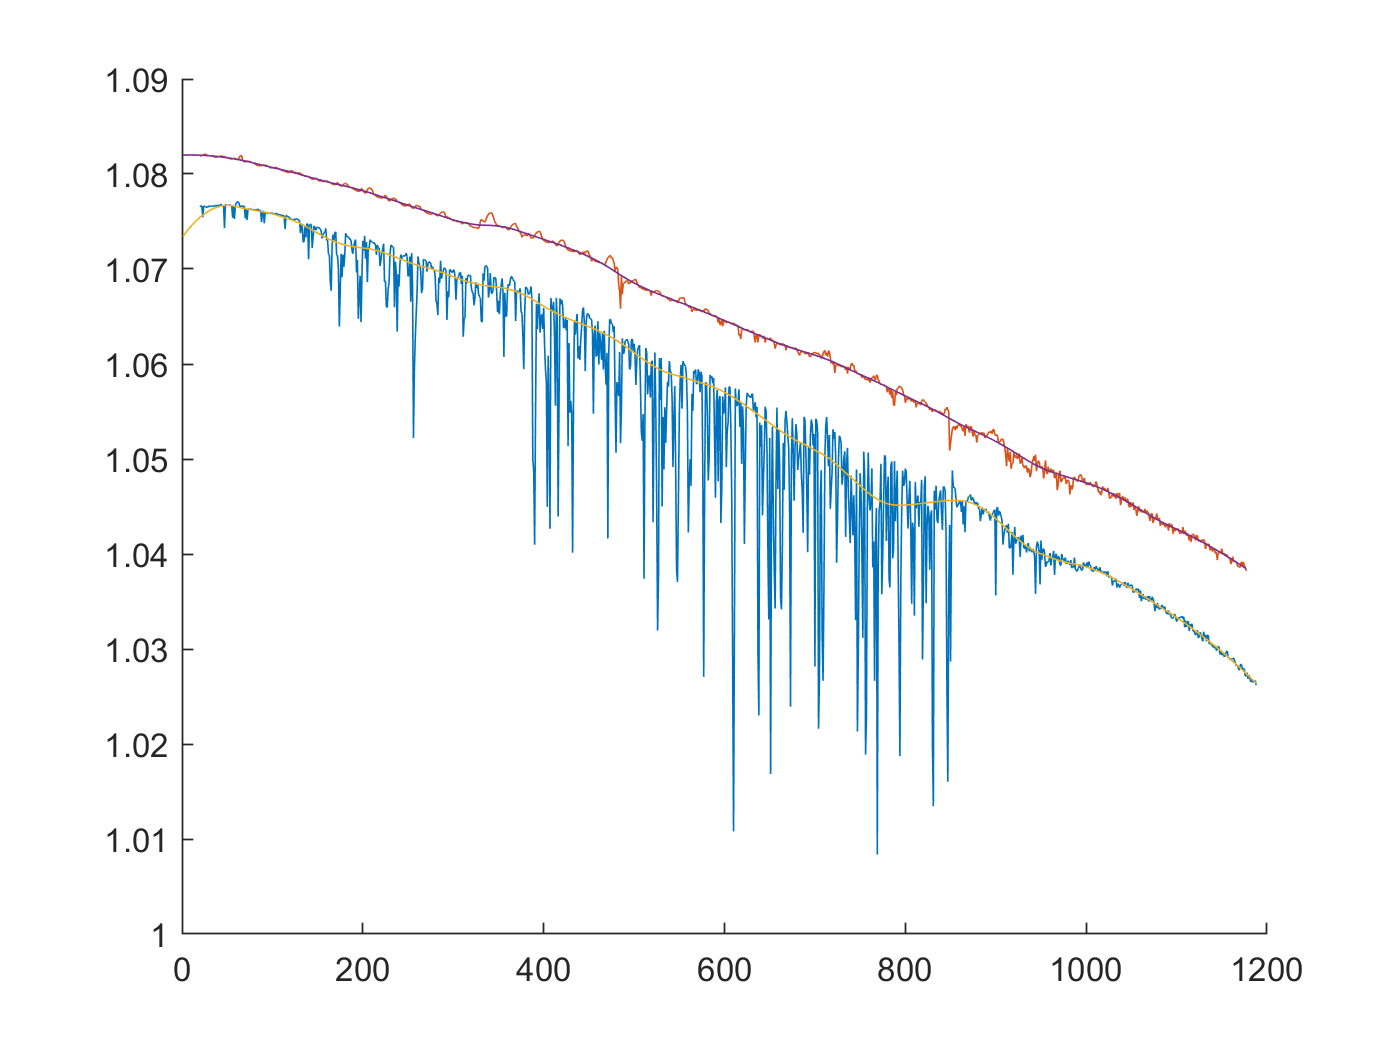

figure
hold on

plot(batch1(1).cycle(20:end),batch1(1).QDischarge(20:end))
plot(batch1(2).cycle(20:end),batch1(2).QDischarge(20:end))    

Idx = batch1(1).QDischarge > 1.3;

plot(batch1(1).cycle,batch1(1).QDischargeSmooth)
plot(batch1(2).cycle,batch1(2).QDischargeSmooth) 

% plot(batch1(1).cycle,batch1(1).QChargePolyfit)
% plot(batch1(2).cycle,batch1(2).QChargePolyfit) 

hold off

Array indices must be positive integers or logical values.

Error in extract_feature_all_new_bat_soc_v3 (line 46)
            [xq, index] = unique(B.cycles(cycleNum).Qc,"first");

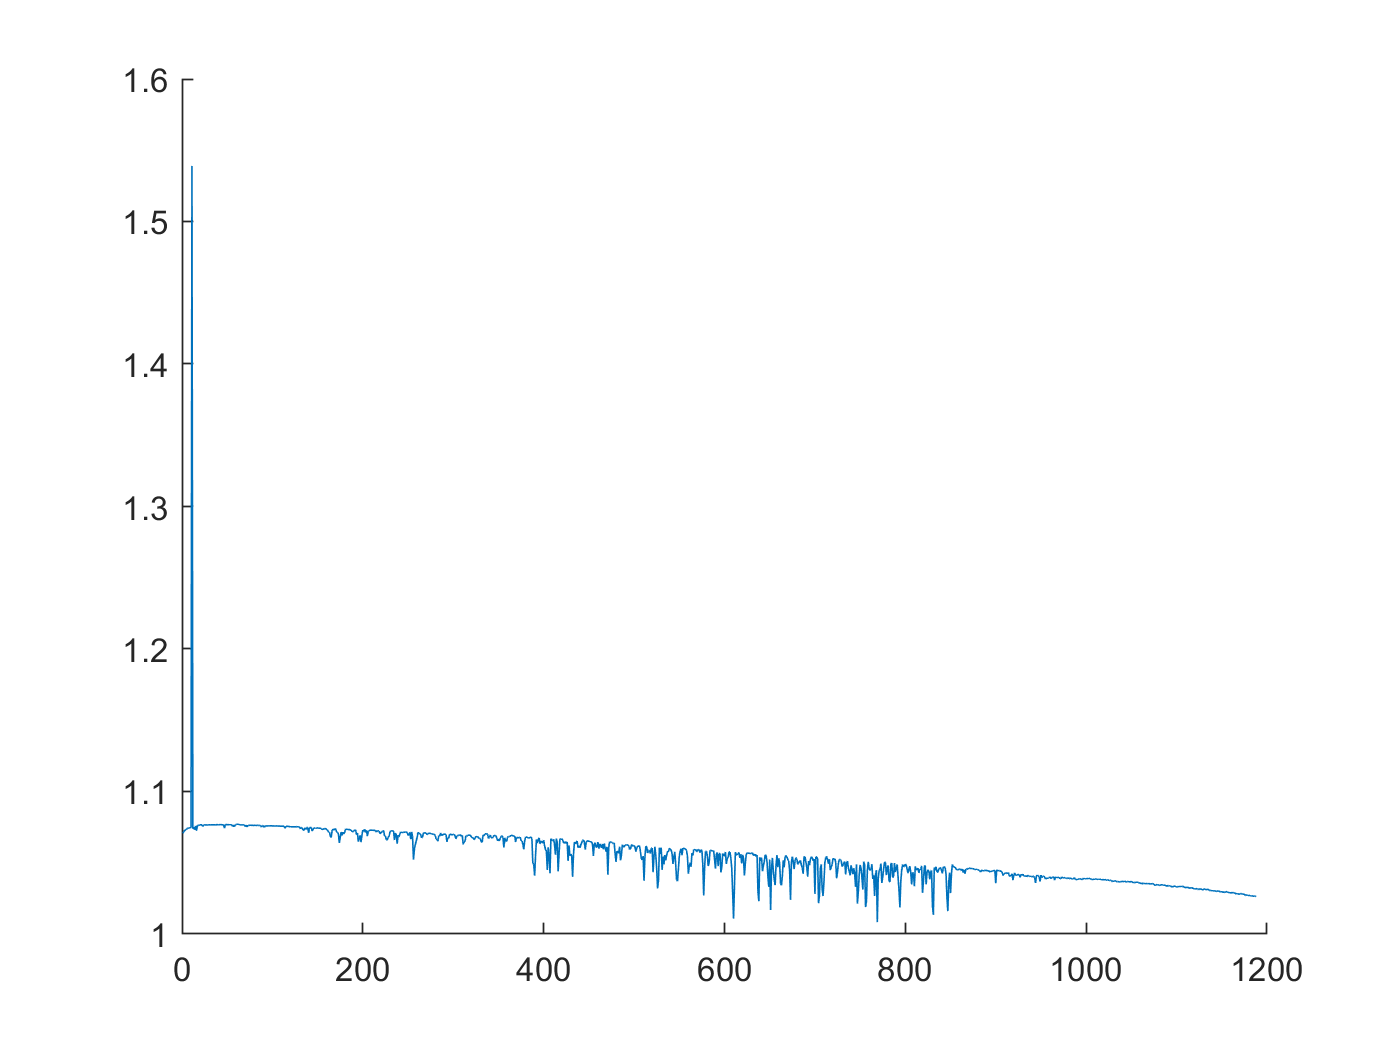

figure
hold on
plot(batch(1).cycle,batch(1).QDischarge)
plot(batch(2).cycle,batch(2).QDischarge)
hold off

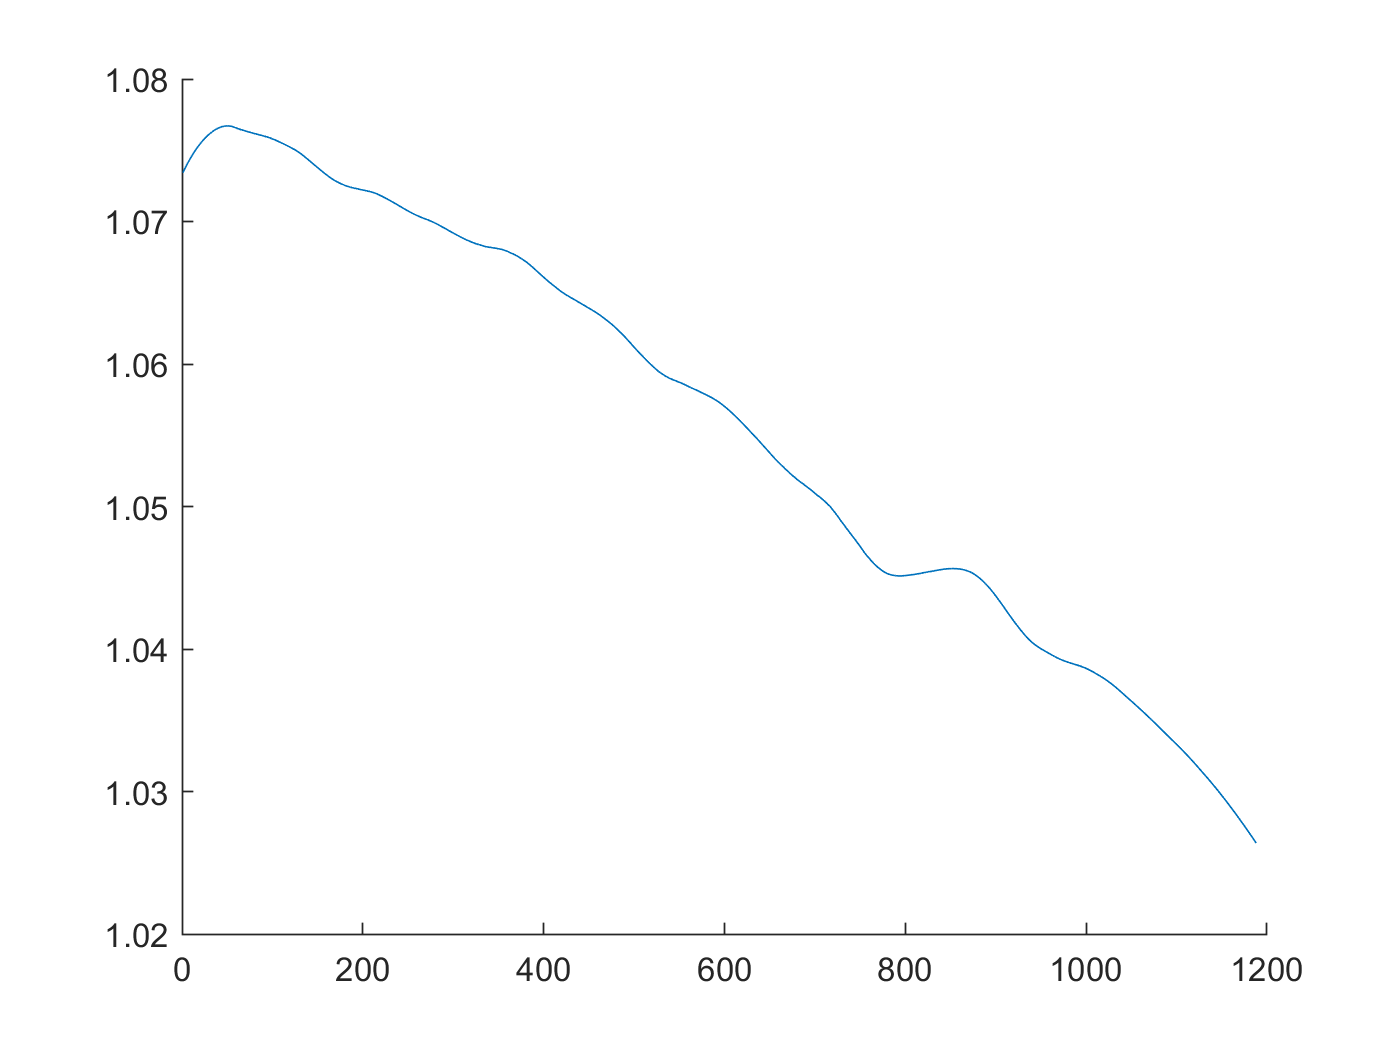


figure
hold on
plot(batch(1).cycle,batch(1).QDischargeSmooth)
plot(batch(2).cycle,batch(2).QDischargeSmooth)
hold off

figure
hold on

plot(batch(1).cycle,batch(1).QDischargePolyfit)

Unrecognized field name "QChargePolyfit".

plot(batch(2).cycle,batch(2).QDoschargePolyfit)
hold off

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

batchNum = 2;


for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,continue_batch2) 
            batNum;
        end    

            batch(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            

    else
        batNum;
    end
end

Unrecognized function or variable 'continue_batch2'.

% #batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))
% batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))
% #remove batteries that do not reach 80% capacity
% del batch1['b1c8']
% del batch1['b1c10']
% del batch1['b1c12']
% del batch1['b1c13']
% del batch1['b1c22']

skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

continue_batch2 = [7 8 9 15 16 ];
continue_batch2 = continue_batch2 +1;
from_batch1 = [0 1 2 3 4];
from_batch1 = from_batch1 + 1;


% [info_str cycleNum VT_leng chargeI dischargeI  ];

idx_info_key = 1;
idx_info_batchnum = 2;
idx_info_batnum = 3;
idx_info_cid = 4;
idx_info_policy = 5;
idx_info_policyreadable = 6;
idx_info_cycle_num = 7;
idx_info_vt_leng = 8;
idx_info_ic_start = 9;
idx_info_ic_end = idx_info_ic_start + VT_leng - 1 ;
idx_info_id_start = idx_info_ic_end + 1;
idx_info_id_end = idx_info_id_start + VT_leng -1;

% [summary VTcharge VTdischarge];


idx_data_cycle = 1;
idx_data_qd =  2;
idx_data_ir = 3;
idx_data_tavg = 4;
idx_data_tmin = 5;
idx_data_tmax = 6;
idx_data_chargetime = 7;
idx_data_qc = 8;
idx_data_vc_start = 9;
idx_data_vc_end = idx_data_vc_start + VT_leng -1;
idx_data_tc_start = idx_data_vc_end + 1;
idx_data_tc_end = idx_data_vc_start + VT_leng -1;
idx_data_vd_start = idx_data_tc_end + 1;
idx_data_vd_end = idx_data_vd_start + VT_leng -1;
idx_data_td_start = idx_data_vd_end + 1;
idx_data_td_end = idx_data_vd_start + VT_leng -1;



% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

continue_batch2 = [7 8 9 15 16 ];
continue_batch2 = continue_batch2 +1;
from_batch2 = [0 1 2 3 4];
from_batch2 = from_batch2 + 1;

for i = size(continue_batch2)
    idx = ismember(batch1_info(:,idx_info_batnum),continue_batch2(i));
    if length(idx) > 1 
        idx
    end
    batch1_info(idx,idx_summary_cycle)
end
aaa = 1


ryan_desc_batch1_info = 'batch1_info';
save('batch1_info.mat','ryan_desc_batch1_info');
save('batch1_info.mat','batch1_info' ,'-append')

ryan_desc_batch1_data = 'batch1_data';
save('batch1_data.mat','ryan_desc_batch1_data');
save('batch1_data.mat','batch1_data' ,'-append')

ryan_desc_batch2_info = 'batch2_info';
save('batch2_info.mat','ryan_desc_batch2_info');
save('batch2_info.mat','batch2_info' ,'-append')

ryan_desc_batch2_data = 'batch2_data';
save('batch2_data.mat','ryan_desc_batch2_data');
save('batch2_data.mat','batch2_data' ,'-append')



load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

new_index = 1;
batchNum = 1;
clear batch3_info;
clear batch3_data;
for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        [info_str, cycleNum, summary,chargeI,dischargeI,VTcharge, VTdischarge,VT_leng ]  = extract_feature_all_new_bat_v2(batchNum,batNum,trainData(batNum));
        batch3_info(new_index,:) = [info_str cycleNum VT_leng chargeI dischargeI  ];
        batch3_data(new_index,:,:) = [summary VTcharge VTdischarge];
        new_index = new_index + 1;
        batNum;
    else
        batNum;
    end
end

ryan_desc_batch3_info = 'batch3_info';
save('batch3_info.mat','ryan_desc_batch3_info');
save('batch3_info.mat','batch3_info' ,'-append')

ryan_desc_batch3_data = 'batch3_data';
save('batch3_data.mat','ryan_desc_batch3_data');
save('batch3_data.mat','batch3_data' ,'-append')
